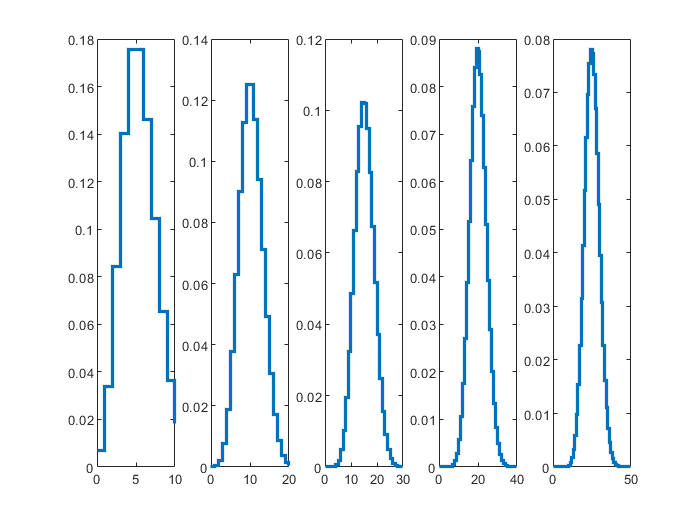

% Lab 2

cr = makedist('Poisson', 'lambda', 5); % Average cosmic-ray background
gr = makedist('Poisson', 'lambda', 7); % Average number of gamma-rays 

%1A

x = 0:10;
subplot(1, 5, 1)
stairs(x,pdf(cr,x),"LineWidth",2)
y = pdf(cr, x);
y1 = y;


for i = 1:4
    c = conv(y,y1);
    subplot(1,5,i+1)
    x = 0:10*(i+1);
    stairs(x,c,"LineWidth",2)
    y = c;
end


% The probability distribution becomes sharper since the majority of the
% data points are not at the peak. More fall along the base of the pdf, so
% the height of the pdf decreases also.

%1B
%As shown above, the peak becomes more refined as more samples are added to
%the base of the distribution. This narrows the peak profile and reduces
%the height. Since the Poisson distribution is narrow, the total profile
%will continue to be narrow as is expected with a convolution operation.



%1C
x1 = 0:10;
y1 = pdf(cr, x1);

u=pdf(cr, x);
v = u;
%subplot(1, 5, 2)
%stairs(x1,y1,"LineWidth",2);
for i = 5:9
    dayx = conv(u,v);
    x = 0:20*(i+1);
    stairs(x/(i+1),dayx,"LineWidth",2)
    xlim([0,15])
    hold on
    u = dayx;
end

Error using stairs (line 53)
X must be same length as Y.

hold off






% for i = 1:9
%     c = conv(y,y1);
%     subplot(2,5,i+1)
%     x = 0:10*(i+1);
%     stairs(x,c/(i+1),"LineWidth",2);
%     y = c;
% end

% As the number of days become larger, the height of the distribution is reduced and
% the base becomes wider. The curve becomes less discrete as the number of
% iterations increases. 
% 
% In terms of the central limit theorem, the
% distribution becomes more Gaussian given sufficient variance. This is
% illustrated by the change in the profile of the curve. As the height of
% the distribution is reduced with successive trials, the inflection of the
% slopes is reduced which is more similar to a Gaussian than a Poisson. The
% means should be the same since the distribution is centered about the
% same value.

%1D
% N = 10 days
background = makedist("Poisson",'lambda',70);
sigma = norminv(cdf(background,70))


%2A
rayl = makedist('Rayleigh');
y = pdf(rayl, x);
plot(x/(i+1),y,"LineWidth",2)
y1 = y;

